# Multi-voxel pattern analysis on fMRI data

Lily Jiang

9/18/2023

Neurotech

clear
load('NeurotechBaM2023/MachineLearningFacesVSHouses/trainfmri3d.mat')

% take the first 3 dimensions and flatten it into one single dimension
% take only columns with 1's (i think?)
fmri2d= squeeze(reshape(train_fmri3d,1,1,[],162))';
r1mask2d=reshape(mask_region1,1,[]);
r2mask2d=reshape(mask_region2,1,[]);
r3mask2d=reshape(mask_region3,1,[]);
r4mask2d=reshape(mask_region4,1,[]);

%Create a variable that is the activity in each voxel of each region over
%time
% if r1mask2d==1, it is a real voxel
r1vals = fmri2d(:,r1mask2d==1);
r2vals = fmri2d(:,r2mask2d==1);
r3vals = fmri2d(:,r3mask2d==1);
r4vals = fmri2d(:,r4mask2d==1);
% NOTE: these matrices are wider than they are tall, which is not optimal
% and might cause overfitting

% Find average in each region
r1avg = mean(r1vals,2);
r2avg = mean(r2vals,2);
r3avg = mean(r3vals,2);
r4avg = mean(r4vals,2);

values = [r1avg, r2avg, r3avg, r4avg];

I split the dataset into 4 regions, then calculated the averages of each of these regions. I did a very basic method of reducing the dataset, and just relied on these averages for the Classification Learner. Each of these averages are 162x1 vectors. I then used various sets of these 4 regions with a Linear SVM to classify the voxels.

The feature sets I tested are:

- All 4 averages

- r2avg, r3avg, r4avg

- r1avg, r3avg, r4avg

- r1avg, r2avg, r4avg

- r1avg, r2avg, r3avg

My reasoning was that I wanted to include a decent amount of data each time, but change something simple so that I can see how impactful each feature was to the algorithm. 

## Assessing the performance of the feature sets

I'm using accuracy and true positive rates for the faces and houses to measure how well the algorithms are. Accuracy is a pretty direct and quick way to look at the classifier, as it is just the proportion that was guessed correctly. I'm also looking at TPRs because it is interesting to see if there is a tendency towards faces over houses, or vice versa.

All 4 averages

- Accuracy: 74.1%

- TPR (faces): 71.6%

- TPR (houses): 76.5%

- Overall a decent accuracy; this actually ended up having the highest accuracy score out of the sets I tested. The TPRs suggest the person was better at recognizing houses than faces.

r2avg, r3avg, r4avg (no r1avg)

- Accuracy: 69.8%

- TPR (faces): 74.1%

- TPR (houses): 65.4%

- A slightly lower accuracy than with all 4 features. The TPRs are notably different between faces and houses; this algorithm suggests that the person was a lot better at recognizing faces than houses.

r1avg, r3avg, r4avg (no r2avg)

- Accuracy: 71.6%

- TPR (faces): 70.4%

- TPR (houses): 72.8%

- This has a slightly better accuracy than the previous run. Interestingly, the TPRs are pretty similar, but houses is slightly higher.

r1avg, r2avg, r4avg (no r3avg)

- Accuracy: 46.9%

- TPR (faces): 58.0%

- TPR (houses): 35.8%

- YIKES what a low accuracy. The TPR values indicate that the person was not great at recognizing faces, but they were really bad at recognizing houses.

r1avg, r2avg, r3avg (no r4avg)

- Accuracy: 70.4%

- TPR (faces): 67.9%

- TPR (houses): 72.8%

- It's an alright algorithm; the TPRs suggest a slightly higher 

## Comparing measurements (graph)

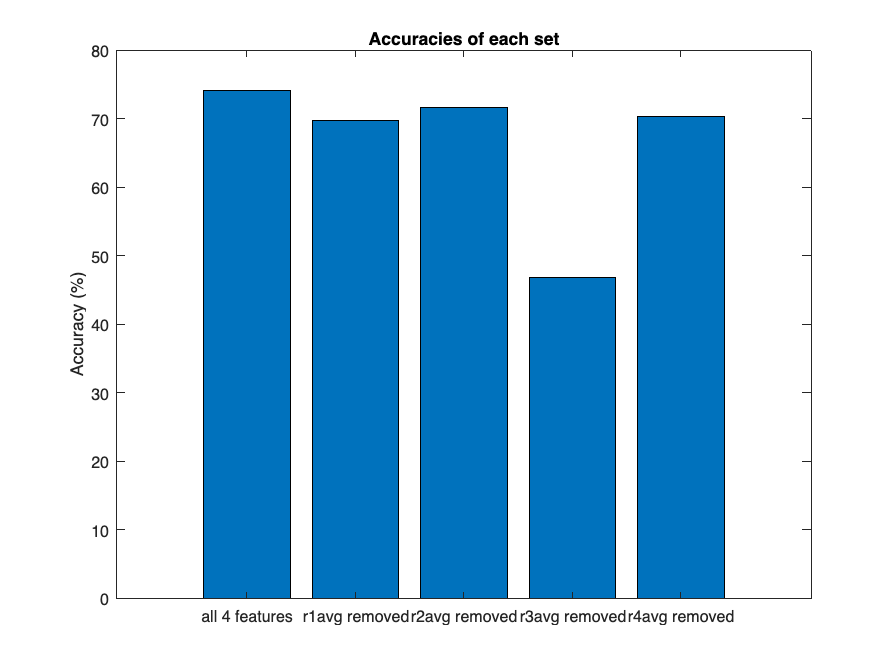

sets = {'all 4 features', 'r1avg removed', 'r2avg removed', 'r3avg removed', 'r4avg removed'};
accuracies = [74.1, 69.8, 71.6, 46.9, 70.4];
tpr = [71.6, 74.1, 70.4, 58.0, 67.9;
       76.5, 65.4, 72.8, 35.8, 72.8];

clf;
figure(1);
bar(accuracies);
xticklabels(sets);
title("Accuracies of each set");
ylabel("Accuracy (%)");

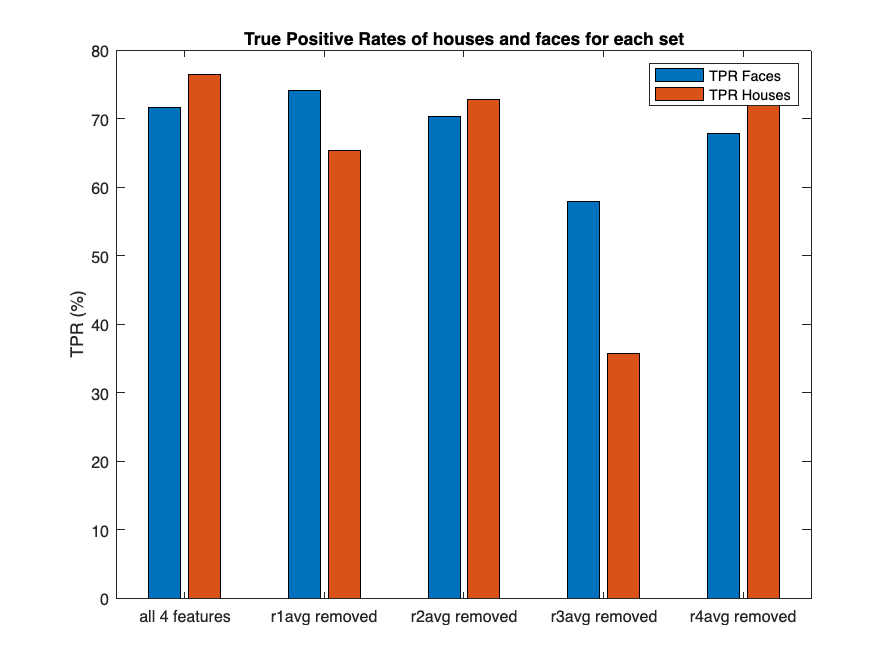


clf;
figure(2);
bar(tpr');
xticklabels(sets);
title("True Positive Rates of houses and faces for each set");
ylabel("TPR (%)");
legend('TPR Faces', 'TPR Houses');

## Test data

load('NeurotechBaM2023/MachineLearningFacesVSHouses/testfmri3d.mat')

fmri2d_test = squeeze(reshape(test_fmri3d,1,1,[],54))';
r1mask2d_test=reshape(mask_region1,1,[]);
r2mask2d_test=reshape(mask_region2,1,[]);
r3mask2d_test=reshape(mask_region3,1,[]);
r4mask2d_test=reshape(mask_region4,1,[]);

%Create a variable that is the activity in each voxel of each region over
%time
r1vals_test = fmri2d_test(:,r1mask2d_test==1);
r2vals_test = fmri2d_test(:,r2mask2d_test==1);
r3vals_test = fmri2d_test(:,r3mask2d_test==1);
r4vals_test = fmri2d_test(:,r4mask2d_test==1);

% Find average in each region
r1avg_test = mean(r1vals_test,2);
r2avg_test = mean(r2vals_test,2);
r3avg_test = mean(r3vals_test,2);
r4avg_test = mean(r4vals_test,2);

values_test = [r1avg_test, r2avg_test, r3avg_test, r4avg_test];

## **Test results**

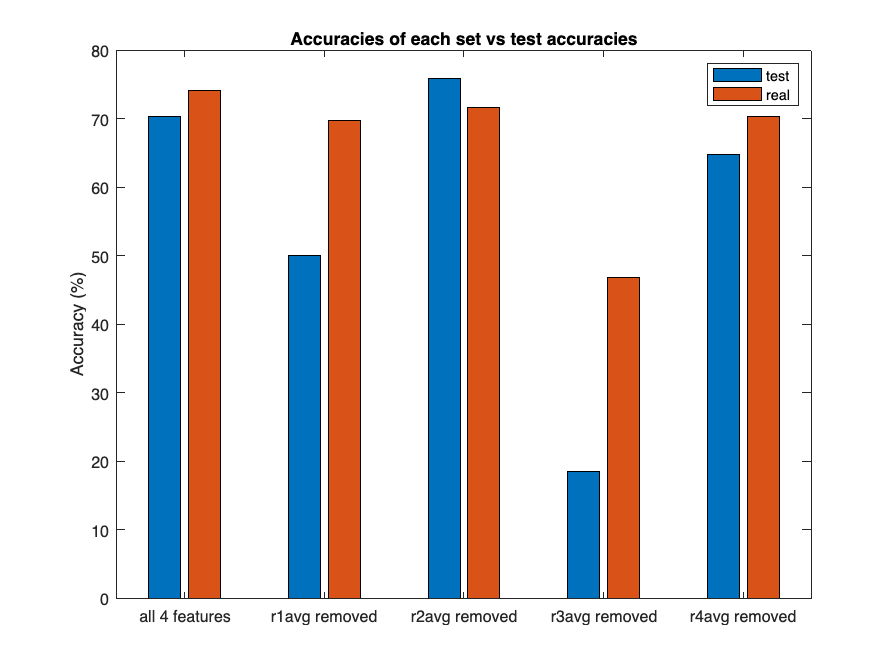

accuracies_test = [70.4, 50.0, 75.9, 18.5, 64.8;
    74.1, 69.8, 71.6, 46.9, 70.4];

clf;
figure(3);
bar(accuracies_test');
xticklabels(sets);
title("Accuracies of each set vs test accuracies");
ylabel("Accuracy (%)");
legend('test', 'real');

**A short summary of what you observed from your analysis and any questions you have. How well did your feature sets perform? What else might you try? What is confusing? [This is intended to help you prepare for the conversation in class.]**

I did not know how to process the tester data of a different size to make it fit with the fmri2d and mask regions and everything. I was only able to get it after someone else realized we needed to change the division amt from 162 to 54 for the sizes to work out. I knew that it was a size issue, but i had no clue which sizes to change and how to fix it.